data=load('C:\3rd sem\NewDataSet\gt.mat');

Error using load
Unable to find file or directory 'C:\3rd sem\NewDataSet\gt.mat'.

trainingDatatbl = objectDetectorTrainingData(gTruth);
imdsTrain = imageDatastore(trainingDatatbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDatatbl(:,'Empty'));
trainingData = combine(imdsTrain,bldsTrain);


inputSize = [300 300 3];
preprocessedTrainingData = transform(trainingData, @(data)preprocessData(data,inputSize));
numAnchors = 6;
[anchorBoxes,meanIoU] = estimateAnchorBoxes(trainingData,numAnchors);
anchorBoxes




featureExtractionNetwork = resnet50;
featureLayer = 'activation_40_relu';
numClasses = 1
lgraph = fasterRCNNLayers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);


options = trainingOptions('sgdm', ...
    'MaxEpochs', 5, ...
    'MiniBatchSize', 1, ...
    'InitialLearnRate', 1e-3, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

[detector,info] = trainFasterRCNNObjectDetector(trainingData, lgraph, options, ...
        'NegativeOverlapRange',[0 0.2], ...
        'PositiveOverlapRange',[0.6 1]);

% Assuming 'detector' is your trained Faster R-CNN object detector
save('trainedDetector.mat', 'detector', 'info');

disp('Trained detector saved as trainedDetector.mat');

newImage = imread('C:\Users\Divyam\Desktop\projects 2022\ML project 2024\NewDataSet\NewDataSet\Images\db196_jpg.rf.abf8d047213fea62f6e3b9070fea600b.jpg')

newImage = 640×640×3 uint8 array
newImage(:,:,1) =

    69    71    70    67    60    55    51    51    44    44    45    47    40    31    31    38    32    26    23    25    25    22    20    22    31    26    19    15    15    16    18    20    20    18    19    24    25    18    16    19     6    15    17     7     3     5     2     0    10     9     8     9    10    12    14    16    15    15    13    10     8     6     4     0     0     0     0     0     0     0     2     3    19    15    16    18    21    18    19    25    27    31    27    18    15    20    21    18    19    19    31    62   107   144   168   176   177   187   193   189   178   161   138   121   108   112   114   113   111   118   130   142   158   161   164   166   172   184   202   214   222   223   225   223   218   213   213   213   216   218   217   215   214   216   221   224   218   219   219   219   219   218   217   219   212   236   226   183   167   197   231   239   232   232   231   230   229   228

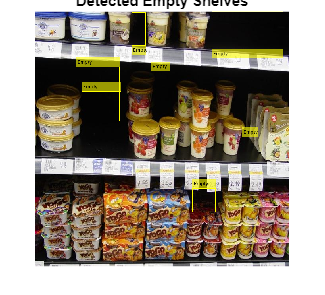


% Detect objects in the new image
[bbox, score, label] = detect(detector, newImage);

% Convert the cell array of labels to a string array
labelStr = string(label);

% Assume that the class of interest is "empty shelf" (adjust based on your labels)
emptyShelfIndices = find(contains(labelStr, 'Empty'));

% Display the results
if ~isempty(emptyShelfIndices)
    % Display the image with detected empty shelves
    detectedImage = insertObjectAnnotation(newImage, 'rectangle', bbox(emptyShelfIndices, :), label(emptyShelfIndices));
    figure;
    imshow(detectedImage);
    title('Detected Empty Shelves');
else
    % Display a message if no empty shelves are found
     detectedImage = insertObjectAnnotation(newImage, 'rectangle', bbox(emptyShelfIndices, :), label(emptyShelfIndices));
    figure;
    imshow(detectedImage);
    title('No Empty Shelves Detected');
end


% Display individual bounding boxes and scores for empty shelves
for i = 1:length(emptyShelfIndices)
    fprintf('Empty Shelf %d: [x, y, width, height] = [%d, %d, %d, %d], Score: %.2f\n', ...
        i, bbox(emptyShelfIndices(i), 1), bbox(emptyShelfIndices(i), 2), ...
        bbox(emptyShelfIndices(i), 3), bbox(emptyShelfIndices(i), 4), score(emptyShelfIndices(i)));
end

Empty Shelf 1: [x, y, width, height] = [55, 358, 56, 67], Score: 0.99
Empty Shelf 2: [x, y, width, height] = [285, 539, 49, 76], Score: 1.00
Empty Shelf 3: [x, y, width, height] = [162, 558, 44, 78], Score: 0.98
Empty Shelf 4: [x, y, width, height] = [589, 237, 30, 105], Score: 0.63
Empty Shelf 5: [x, y, width, height] = [519, 353, 105, 178], Score: 1.00
Empty Shelf 6: [x, y, width, height] = [347, 365, 68, 75], Score: 1.00
Empty Shelf 7: [x, y, width, height] = [1, 134, 65, 64], Score: 1.00
Empty Shelf 8: [x, y, width, height] = [171, 361, 49, 139], Score: 0.92
Empty Shelf 9: [x, y, width, height] = [36, 77, 42, 135], Score: 0.73


% Assuming emptyShelfIndices is an array containing the indices of the empty shelves

% Initialize arrays to store center coordinates of each empty shelf
x_center = zeros(1, numel(emptyShelfIndices));
y_center = zeros(1, numel(emptyShelfIndices));

% Calculate center coordinates for each empty shelf
for i = 1:numel(emptyShelfIndices)
    x_center(i) = bbox(emptyShelfIndices(i), 1) + bbox(emptyShelfIndices(i), 3) / 2;
    y_center(i) = bbox(emptyShelfIndices(i), 2) + bbox(emptyShelfIndices(i), 4) / 2;
end


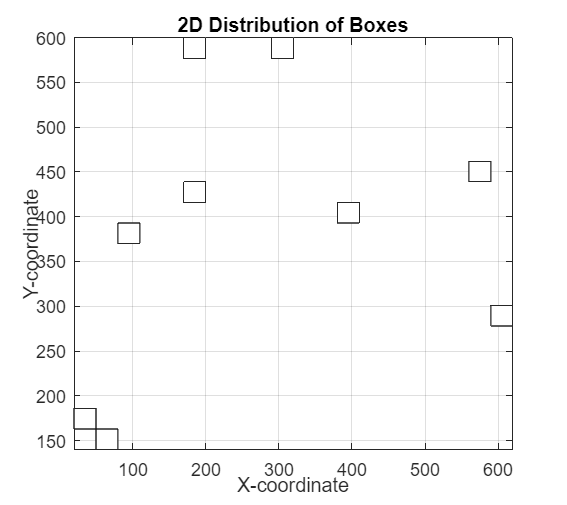

% Define the number of bins for the heatmap
numBins = 20;

% Create a 2D histogram
h = histogram2(x_center, y_center, numBins, 'DisplayStyle', 'tile');

% Set colormap for the heatmap


% Add labels and title
xlabel('X-coordinate');
ylabel('Y-coordinate');
title('2D Distribution of Boxes');
colormap("gray")